% Joint axis directions
H = NaN([3 6]);
for i = 1:6
    H(:,i) = rand_unit_vec();
end

% Joint offsets in 0 position
P = NaN([3 7]);
for i = 1:7
    P(:,i) = rand_unit_vec()* (rand()*5 +5);
end

% Spherical shoulder
%P(:,2:3) = 0;

kin.H = H;
kin.P = P;
kin.joint_type = zeros([1 6]);

theta = rand([6 1])*2*pi - pi

theta =    -1.0577
   -2.1851
   -0.9550
   -2.3772
    2.4137
   -2.5492



[R_0T, p_0T] = fwdkin(kin, theta)

R_0T =     0.8683   -0.4735   -0.1478
    0.3332    0.3358    0.8810
   -0.3675   -0.8142    0.4494


p_0T =     7.2324
   31.0749
   31.8322



q1 = theta(1)

q1 = -1.0577

q2 = theta(2)

q2 = -2.1851


h_dot_h = gen_6_dof_alignment_vs_q12(q1, q2, R_0T, p_0T, kin)

h_dot_h =     1.0000    0.6958



theta_range = linspace(-pi, pi, 180);

[QQ1, QQ2] = meshgrid(theta_range, theta_range);
alignment_mat = NaN(size(QQ1));

for i = 1:numel(QQ1)
    h_dot_h = gen_6_dof_alignment_vs_q12(QQ1(i), QQ2(i), R_0T, p_0T, kin);
    if ~isempty(h_dot_h)
        alignment_mat(i) = max(h_dot_h);
    end
end


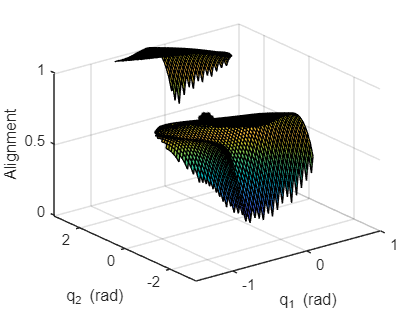

alignment_mat_max = alignment_mat;
alignment_mat_max(alignment_mat<0.999) = NaN;

surf(QQ1, QQ2, alignment_mat)
hold on
surf(QQ1, QQ2, alignment_mat_max, 'FaceColor','r')
plot3(q1, q2, 1, 'k*', 'LineWidth',10)
hold off
xlabel("q_1 (rad)")
ylabel("q_2 (rad)")
zlabel("Alignment")

[sol_1, f_val_1] = fminsearch(@(x)(-max(gen_6_dof_alignment_vs_q12(x(1), x(2), R_0T, p_0T, kin))),[q1 q2])

sol_1 =    -1.0577   -2.1851


f_val_1 = -1.0000

[sol_2, f_val_2] = fminsearch(@(x)(-max(gen_6_dof_alignment_vs_q12(x(1), x(2), R_0T, p_0T, kin))),[-0.087754 -2.755])

sol_2 =    -0.1119   -3.4151


f_val_2 = -1.0000

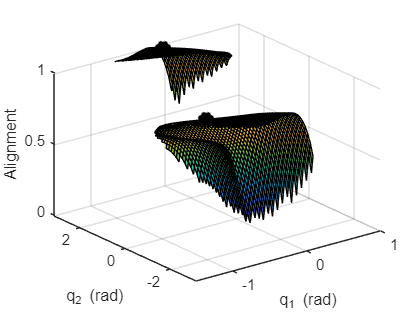

sol_2 = wrapToPi(sol_2);
%[sol_3, f_val_3] = fminsearch(@(x)(-max(gen_6_dof_alignment_vs_q12(x(1), x(2), R_0T, p_0T, kin))),[6.2 0.84])
%[sol_4, f_val_4] = fminsearch(@(x)(-max(gen_6_dof_alignment_vs_q12(x(1), x(2), R_0T, p_0T, kin))),[4.02 0.14])


surf(QQ1, QQ2, alignment_mat)
hold on
surf(QQ1, QQ2, alignment_mat_max, 'FaceColor','r')
%plot3(q1, q2, 1, 'k*', 'LineWidth',10)
plot3(sol_1(1), sol_1(2), 1, 'k*', 'LineWidth',10)
plot3(sol_2(1), sol_2(2), 1, 'k*', 'LineWidth',10)
%plot3(sol_3(1), sol_3(2), 1, 'k*', 'LineWidth',10)
%plot3(sol_4(1), sol_4(2), 1, 'k*', 'LineWidth',10)
hold off
xlabel("q_1 (rad)")
ylabel("q_2 (rad)")
zlabel("Alignment")

%for soln = [sol_1' sol_2' sol_3' sol_4']
for soln = [sol_1' sol_2']
    [Q1, Q2, Q3, Q4, Q5, Q6] = gen_6_dof_soln_given_q12(sol_1(1), sol_1(2), R_0T, p_0T, kin)
    for i = 1:length(Q1)
        [R_0T_test, p_0T_test] = fwdkin(kin, [Q1(i) Q2(i) Q3(i) Q4(i) Q5(i) Q6(i)]);
        norm(R_0T - R_0T_test) + norm(p_0T - p_0T_test)
    end
end

Q1 = -1.0577

Q2 = -2.1851

Q3 = -0.9550

Q4 = -2.3772

Q5 = 2.4137

Q6 = -2.5492

ans = 1.4347e-13

Q1 = -1.0577

Q2 = -2.1851

Q3 = -0.9550

Q4 = -2.3772

Q5 = 2.4137

Q6 = -2.5492

ans = 1.4347e-13

%theta_12 = rand([2 1])*2*pi - pi
theta_12 = theta(1:2)

theta_12 =     0.8036
    1.7089



% Appply forward kin to get elbow position
kin_12 = kin;
kin_12.joint_type = zeros([1 2])

kin_12 = struct with fields:
             H: [3×6 double]
             P: [3×7 double]
    joint_type: [0 0]


[R_03, p_03] = fwdkin(kin_12, theta)

R_03 =    -0.2865    0.1202    0.9505
    0.9052   -0.2910    0.3096
    0.3138    0.9491   -0.0255


p_03 =     0.5739
    0.3645
   -0.9348



p_3T = p_0T - p_03

p_3T =    -2.5036
    3.3372
    4.4851




p_01 = P(:,1);
p_12 = P(:,2);
p_23 = P(:,3);
p_34 = P(:,4);
p_45 = P(:,5);
p_56 = P(:,6);
p_6T = P(:,7);
R_1 = rot(H(:,1),theta(1));
R_2 = rot(H(:,2),theta(2));
R_3 = rot(H(:,3),theta(3));
R_4 = rot(H(:,4),theta(4));
R_5 = rot(H(:,5),theta(5));
R_6 = rot(H(:,6),theta(6));

%p_0T - R_0T' * (p_34 + R_4*(p_45 + R_5*(p_56+R_6*p_6T)))
%p_03

%-p_6T + R_6'*(-p_56+R_5'*(-p_45 + R_4'*(-p_34)))
%-R_0T'*p_3T

P_T3 = -R_0T'*p_3T;
-p_45 + R_4'*(-p_34)

ans =    -2.2650
   -4.5668
   -3.3329


R_5*(p_56+R_6*(P_T3+p_6T))

ans =    -2.2650
   -4.5668
   -3.3329



% Use gen sp3 to find q4 q5 q6
tic
[t4, t5, t6] = gen_subproblem3_linear(-p_45,-p_34,p_56,P_T3+p_6T,-H(:,4),H(:,5),H(:,6))

t4 =     2.9703   -0.5091


t5 =    -1.9350    3.0094


t6 =    -2.2690   -1.9805


toc

Elapsed time is 0.091914 seconds.


%[theta1, theta2, theta3] = gen_subproblem3_linear(p0,p1,p2,p3,k1,k2,k3)
% p0 + R(k1,theta1)p1 = R(k2,theta2)(p2+R(k3,theta3)p3)

% Check for alignment of h_3

h_3_base = R_03*H(:,3)

h_3_base =     0.3220
    0.0720
    0.9440



i = 1;
h_3_T = R_0T* rot(H(:,6),-t6(i))*rot(H(:,5),-t5(i))*rot(H(:,4),-t4(i))*H(:,3)

h_3_T =     0.3220
    0.0720
    0.9440


dot(h_3_base,h_3_T)

ans = 1.0000

-p_23+R_2'*(-p_12+R_1'*(p_0T-p_01))

ans =     5.1456
    2.9850
   -1.4606



R_3*(p_34 + R_4*(p_45 + R_5*(p_56+R_6*p_6T)))

ans =     5.1456
    2.9850
   -1.4606




% Find q_3 using sp1
%t3 = subproblem1_linear(p1, p_0T-p_03, H(:,3))



t3 = subproblem1_linear( ...
    p_34 + R_4*(p_45 + R_5*(p_56+R_6*p_6T)), ...
    -p_23+R_2'*(-p_12+R_1'*(p_0T-p_01)), ...
    H(:,3))

t3 = 2.7197

%  p2 = rot(k, theta)*p1


p0 = -p_45 

p0 =     0.2036
    0.8355
    0.5481


p1 = -p_34

p1 =     0.4990
    1.2144
    0.7294


p2 = p_56

p2 =     0.2711
    0.4827
    0.1524


p3 = P_T3+p_6T

p3 =     1.8460
    0.4939
   -0.8456


k1 = -H(:,4)

k1 =    -0.2254
   -0.0964
   -0.2239


k2 = H(:,5)

k2 =     0.2317
    0.0227
    0.0849


k3 = H(:,6)

k3 =     0.0747
    0.2226
    0.2815



t1 = theta(4) 

t1 = 0.4788

t2 = theta(5)

t2 = 1.1521

t3 = theta(6)

t3 = 0.2928


norm(p0 + rot(k1,t1)*p1 - rot(k2,t2)*(p2+rot(k3,t3)*p3))

ans = 1.4937e-15

function e = rand_unit_vec()
    e = rand([3 1]);
    e = e / norm(e);
end